masterImage = imread("imageGeneratedFrom3D\Acquisizioni_Scavone_000\immagine_1_0.0924.jpg");

slave = imread("imageGeneratedFrom3D\Acquisizioni_Scavone_021\immagine_1_0.0924.jpg");

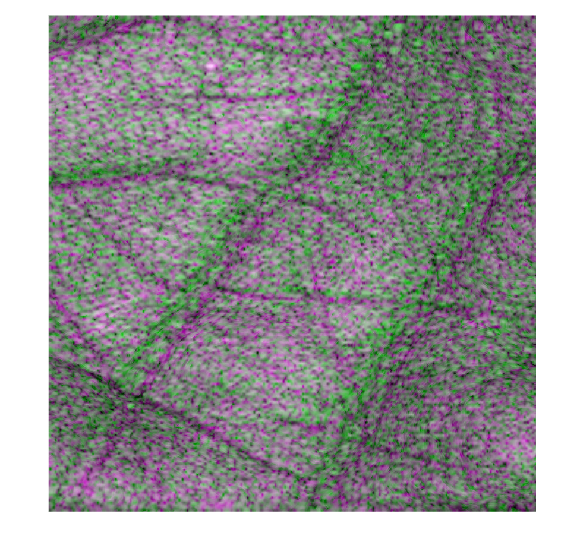

imshowpair(masterImage,slave,"Scaling","joint");

% All'interno di questa funzione, 
% vengono impostate varie opzioni, 
% tra cui il tipo di ottimizzazione, 
% le metriche di similarità e altri parametri che 
% influenzano come l'immagine viene registrata. 
% Le metriche di similarità misurano quanto bene 
% due immagini coincidono durante il processo di
% registrazione. Monomodal significa che le immagini
% sono acquisite con lo stesso sensore

[optimizer,metric] = imregconfig("monomodal");


% Questa funzione cerca di trovare una trasformazione che 
% allineerà l'immagine "slave" rispetto all'immagine 
% "masterImage"
tform = imregtform(slave,masterImage,"rigid",optimizer,metric);

% Una volta ottenuta la trasformazione, viene utilizzata la funzione 
% imwarp per applicarla all'immagine "slave". 
% Questo significa che ogni pixel nell'immagine "slave"
% viene trasformato e posizionato in base alla trasformazione calcolata.
movingRegistered = imwarp(slave,tform,"OutputView",imref2d(size(masterImage)));

% Converti l'immagine master in double se non lo è già
master = im2double(masterImage);
moving = im2double(movingRegistered);

% Calcola l'Errore Quadratico Medio (MSE)
mse = immse(moving, master);

% Calcola l'Errore Quadratico Medio Normalizzato (NMSE)
nmse = mse / mean(master(:).^2);

fprintf("Errore Quadratico Medio (MSE) per l'immagine %d: %.4f\n", mse);

Errore Quadratico Medio (MSE) per l'immagine 3.008427e-02: 

fprintf("Errore Quadratico Medio Normalizzato (NMSE) per l'immagine %d: %.4f\n", nmse);

Errore Quadratico Medio Normalizzato (NMSE) per l'immagine 1.419857e-01: 

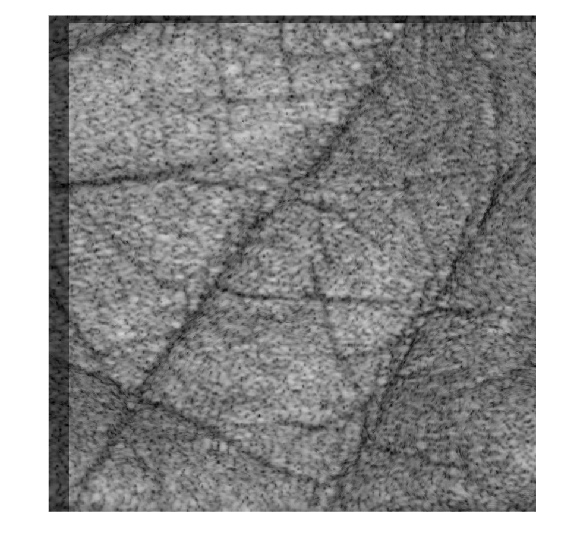

imshowpair(masterImage,movingRegistered,"blend","Scaling","joint");

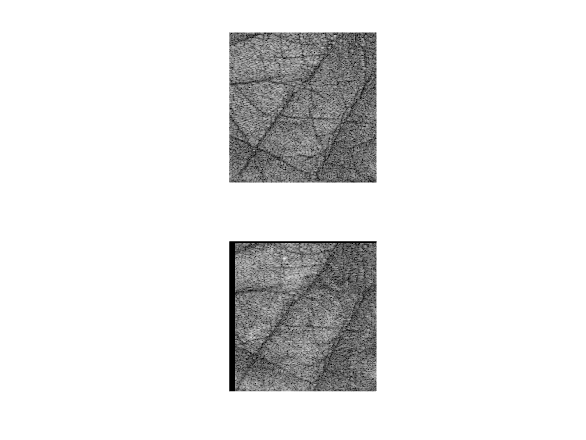

figure;subplot(2,1,1);imshow(masterImage);
subplot(2,1,2);imshow(movingRegistered);